clf
n = 39;
img = imread('images/alberta/mining_1984.png');
imsize = size(img);
imsize(4) = n;
ims = ones(imsize);
for i=1:n
    ims(:,:,:,i) = imread('images/alberta/mining_' + string(1983+i) + '.png');
end

Error using imread>get_full_filename (line 579)
Unable to find file "images/mining/mining_1984.png".

Error in imread (line 372)
        fullname = get_full_filename(filename);

img = imread('images/alberta/mining_2022.png');
img = imresize(img, 0.5);
img = im2double(img);
r = img(:,:,1);
r = reshape(r.',1,[]);
g = img(:,:,2);
g = reshape(g.',1,[]);
b = img(:,:,3);
b = reshape(b.',1,[]);

hsv = rgb2hsv(img);
h = hsv(:,:,1);
h = reshape(h.',1,[]);
s = hsv(:,:,2);
s = reshape(s.',1,[]);
v = hsv(:,:,3);
v = reshape(v.',1,[]);
x = 1:length(img);
x = repmat(x, length(img(:,1)), 1);
x = reshape(x.',1,[]);
y = transpose(1:length(img(:,1)));
y = repmat(y, 1, length(img));
y = reshape(y.',1,[]);

r_scale = r/max(r);
g_scale = g/max(g);
b_scale = b/max(b);

h_scale = h(1:1:end)/max(h);
s_scale = s(1:1:end)/max(s);
v_scale = v(1:1:end)/max(v);
x_scale = x(1:1:end)/max(x);
y_scale = y(1:1:end)/max(y);


data = [2*h_scale; s_scale; 2*v_scale; x_scale; y_scale]';

minpts = 100;


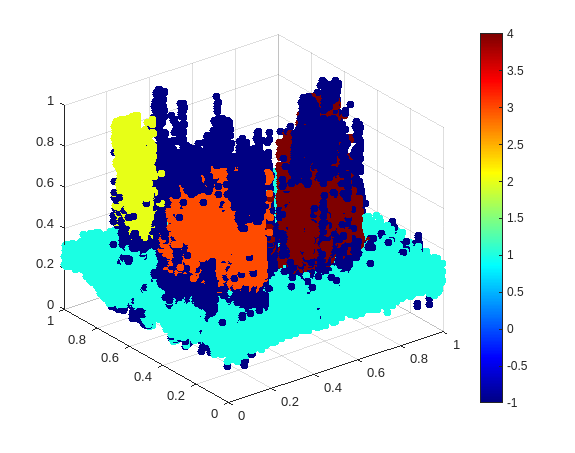

[idx, corepts] = dbscan(data, 0.12, 220); % 0.1 30
% scatter3(h_scale, s_scale, v_scale)
scatter3(y_scale, x_scale, v_scale, [], idx, 'filled')
colorbar
colormap jet

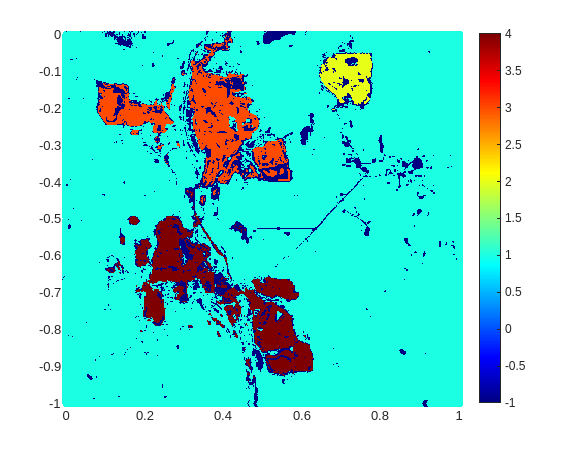

scatter(x_scale, -y_scale, [], idx, 'filled')
colorbar
colormap jet


rng('default') % For reproducibility

% Parameters for data generation
N = 300;  % Size of each cluster
r1 = 0.5; % Radius of first circle
r2 = 5;   % Radius of second circle
theta = linspace(0,2*pi,N)';

X1 = r1*[cos(theta),sin(theta)]+ rand(N,1); 
X2 = r2*[cos(theta),sin(theta)]+ rand(N,1);
X = [X1;X2] % Noisy 2-D circular data set

X =     1.3147    0.8147
    1.4057    0.9163
    0.6265    0.1480
    1.4124    0.9449
    1.1306    0.6743
    0.5948    0.1500
    0.7745    0.3414
    1.0415    0.6202
    1.4505    1.0412
    1.4560    1.0589


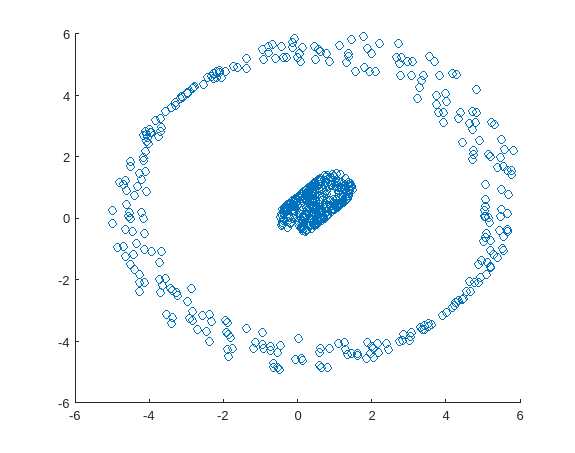

scatter(X(:,1),X(:,2))

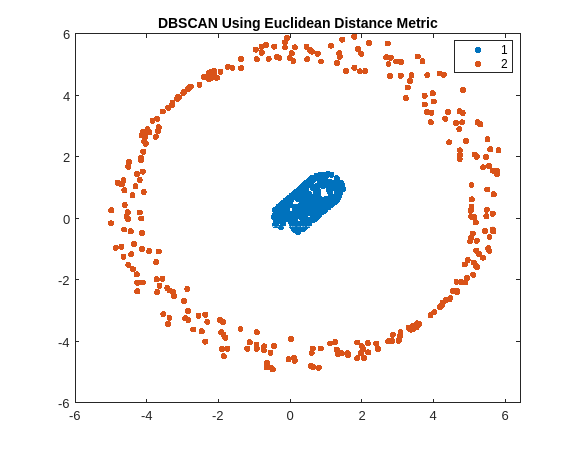


idx = dbscan(X,1,5); % The default distance metric is Euclidean distance

gscatter(X(:,1),X(:,2),idx);
title('DBSCAN Using Euclidean Distance Metric')